close all
clear
clc

## Cargar datos

load("data_for_animation.mat");

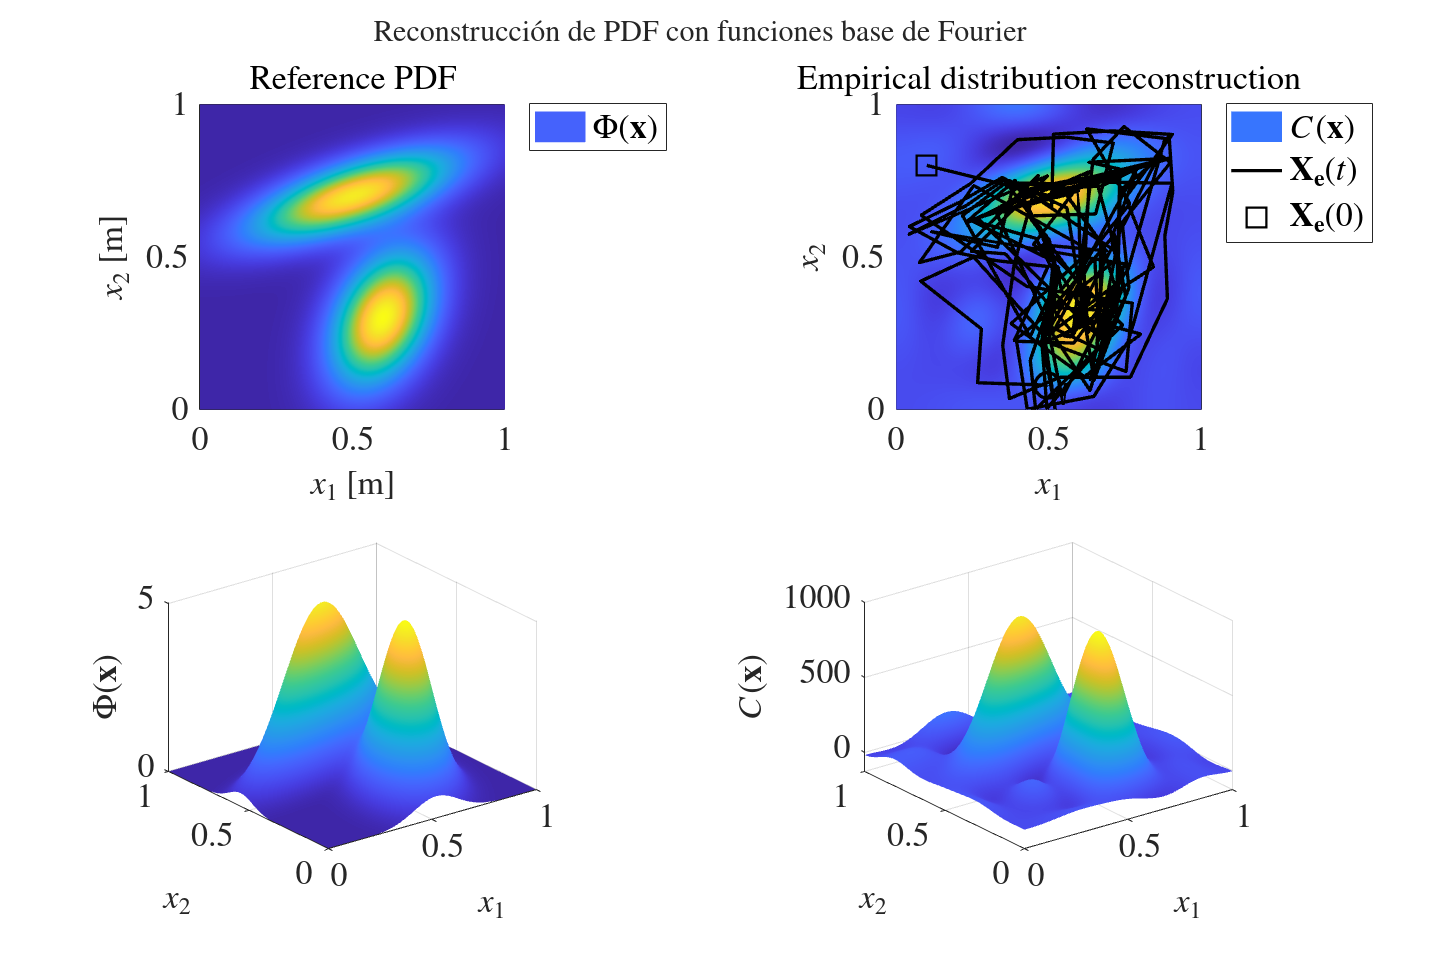


%Empirical distribution animation 1st Order system

figh = figure;
figh.Units = "centimeters";
figh.Position = [5, 5, 54, 36];
figh.Units = "pixels";
layouth = tiledlayout(figh,2,2);
title(layouth, "Reconstrucci\'on de PDF con funciones base de Fourier",...
    "interpreter", "latex", "FontSize", 18)
colormap default

%Primera iteración
nexttile
pcolor(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)),...
    "FaceColor","interp","EdgeColor","none")
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Reference PDF")
xlabel('$x_1$ [m]')
ylabel('$x_2$ [m]')
axis equal tight
grid on
legend("$\Phi(\mathbf{x})$", 'Location','northeastoutside')

nexttile
Empdist_plane_plot = pcolor(x_1_grid, x_2_grid, reshape(C_x_reg(:,1), length(x_2), length(x_1)),...
    "FaceColor","interp","EdgeColor","none");
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Empirical distribution reconstruction")
xlabel('$x_1$')
ylabel('$x_2$')
axis equal tight
grid on
hold on
estados_plot = plot(estados(1,1),estados(1,2),"Color", "black", 'LineWidth',2);
plot_2_2 = plot(estados(1,1),estados(1,2),'ksq','MarkerSize',15,'LineWidth',2);
circ_plot = plot(estados(1,1),estados(1,2),"ok", 'MarkerSize',15,'LineWidth',2);
hold off
legend([Empdist_plane_plot, estados_plot, plot_2_2], {"$C(\mathbf{x})$", "$\mathbf{X_e}(t)$", "$\mathbf{X_e}(0)$"},...
    'Location','northeastoutside')

nexttile
surf(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)),...
    "EdgeColor","none", "FaceColor","interp")
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
xlabel('$x_1$')
ylabel('$x_2$')
zlabel('$\Phi(\mathbf{x})$')
grid on

nexttile
Empdist_surf_plot = surf(x_1_grid, x_2_grid, reshape(C_x_reg(:,1), length(x_2), length(x_1)),...
    "EdgeColor","none", "FaceColor","interp");
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
xlabel('$x_1$')
ylabel('$x_2$')
zlabel('$C(\mathbf{x})$')
grid on

set(findall(figh,'-property','Interpreter'),'Interpreter','latex') 
set(findall(figh,'-property','TickLabelInterpreter'),'TickLabelInterpreter','latex')
set(findall(figh, "-property", "FontSize"), "FontSize", 20)

for i = 2:length(t_1)
    % Delay (if needed)
    pause(0.0001)
    
    % Actualizar distribucion empirica en el plano
    Empdist_plane_plot.CData = reshape(C_x_reg(:,i), length(x_2), length(x_1));
    
    % Aumentar los datos de trayectoria y actualizar la posición actual
    estados_plot.XData(end + 1) = estados(i,1);
    estados_plot.YData(end + 1) = estados(i,2);
    circ_plot.XData = estados(i,1);
    circ_plot.YData = estados(i,2);
    Empdist_surf_plot.ZData = reshape(C_x_reg(:,i), length(x_2), length(x_1));

end